# Plotting

One of the most important uses of MATLAB is the ability to visualize your data. When plotting in MATLAB, there are few nuances that we have to pay close attention to. By the end of this notebook, you will be able to

- Plot two vectors of the same length against each other

- Add features such as titles, colors, and legends to your graph

- Create a histogram and a scatter plot of pre-loaded data. 

## The `plot` function

Recall that when we typically sketch the graph of a function, the domain is plotted on the $x$-axis and the range is plotted on the $y$-axis:

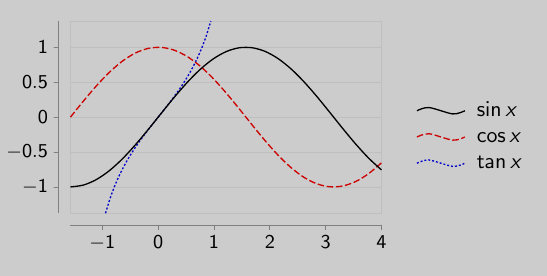

If you just want to graph a function in MATLAB, the first thing you'll need to do is create a vector containing the $x$-values that will be input into our function. This is typically done using `linspace:`

%% Create a vector of x-values

x = linspace(-10,10,1000);

Now we can define the function that we wish to plot and use the `plot` command to generate a figure:

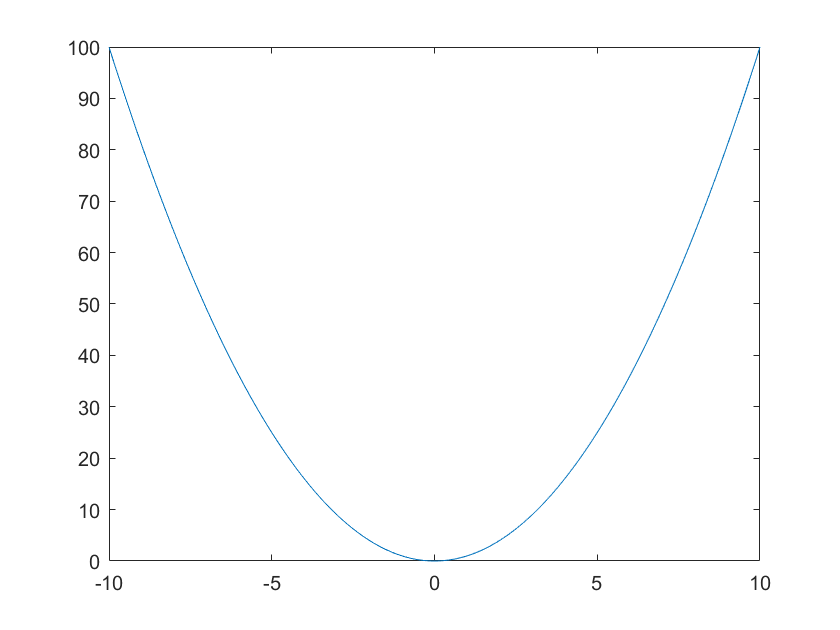

%% Plot y = x^2
y = x.^2;
plot(x,y)


(Notice we used `.^ `to indicate that we wanted to square each entry in `x `as opposed to multiply `x` by itself.). 

You try: Plot the function $f(x) = \sin(x)$ on the interval from $0$ to $2\pi$. Store your $x$ and $y$ values in vectors called `x1` and `y1` respectively. 

%% Code here.

x1 = linspace(0, 2*pi, 1000)

x1 =          0    0.0063    0.0126    0.0189    0.0252    0.0314    0.0377    0.0440    0.0503    0.0566    0.0629    0.0692    0.0755    0.0818    0.0881    0.0943    0.1006    0.1069    0.1132    0.1195    0.1258    0.1321    0.1384    0.1447    0.1509    0.1572    0.1635    0.1698    0.1761    0.1824    0.1887    0.1950    0.2013    0.2076    0.2138    0.2201    0.2264    0.2327    0.2390    0.2453    0.2516    0.2579    0.2642    0.2704    0.2767    0.2830    0.2893    0.2956    0.3019    0.3082


y1 = sin(x1)

y1 =          0    0.0063    0.0126    0.0189    0.0252    0.0314    0.0377    0.0440    0.0503    0.0566    0.0629    0.0691    0.0754    0.0817    0.0879    0.0942    0.1005    0.1067    0.1130    0.1192    0.1255    0.1317    0.1379    0.1442    0.1504    0.1566    0.1628    0.1690    0.1752    0.1814    0.1876    0.1937    0.1999    0.2061    0.2122    0.2184    0.2245    0.2306    0.2367    0.2428    0.2489    0.2550    0.2611    0.2672    0.2732    0.2793    0.2853    0.2913    0.2973    0.3033


plot(x1,y1)


We can add multiple graphs to a single plot using the `hold on` feature:

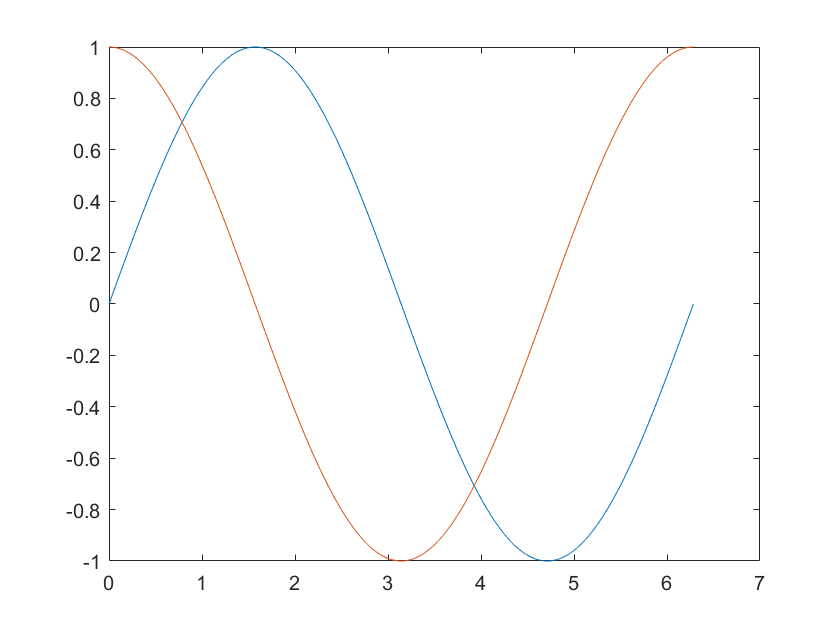

hold on % tells MATLAB not to create a new plot
y2 = cos(x1);
plot(x1,y2)
hold off % always enter this when you are done plotting. 

## Getting Fancy

Most likely, you will want to present your data in a visually-appealing manner. Plots should also be understandable by the general public, so you will want to add things like titles, colors, and legends. 

You may wish to change up the style and color of the curves on your plots. For this, `plot` can accept a third argument that allows you to specify color, line style, and marker style. For example, the command

`plot(x,y,'r--o')`

produces a plot of `y` against `x `using a red (`r)`, dashed (`--)`, line with circle (`o`) markers. 

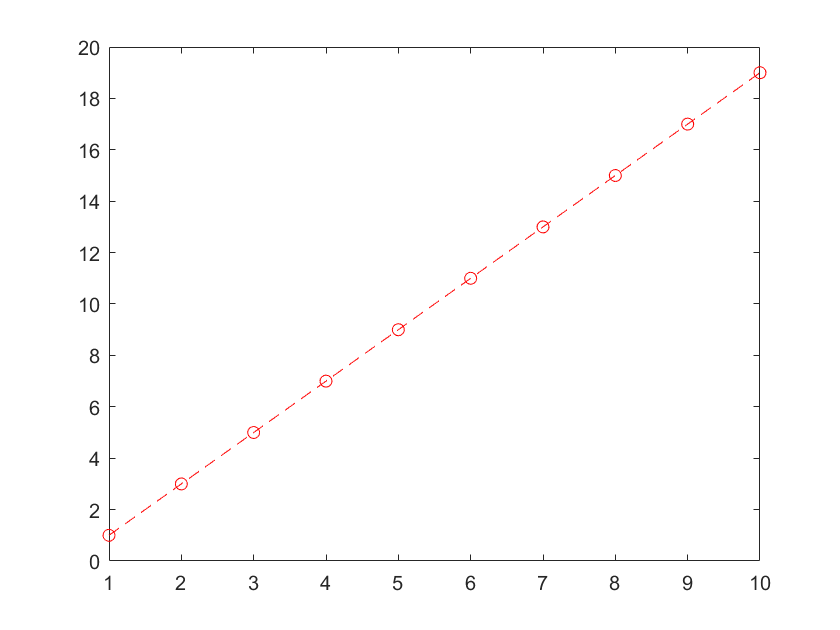

%% Run this code to generate a fancy plot

x3 = linspace(1,10,10);
y3 = 2*x3-1;
plot(x3,y3,'r--o')

For a full list of the style characters you can use visit: [https://www.mathworks.com/help/matlab/ref/linespec.html](https://www.mathworks.com/help/matlab/ref/linespec.html).You'll also see in LineSpec documentation that you can specify a line width. 

You try: Create a plot containing the graphs of $y=2x^2-1$ and $y = \sqrt{x}$. Play around with different colors, styles, and line widths. 

%% Code here.

%% Sample Solution

clc % clear variables to avoid confusion 

x = linspace(0,10,1000) % pick your domain wisely!

x =          0    0.0100    0.0200    0.0300    0.0400    0.0501    0.0601    0.0701    0.0801    0.0901    0.1001    0.1101    0.1201    0.1301    0.1401    0.1502    0.1602    0.1702    0.1802    0.1902    0.2002    0.2102    0.2202    0.2302    0.2402    0.2503    0.2603    0.2703    0.2803    0.2903    0.3003    0.3103    0.3203    0.3303    0.3403    0.3504    0.3604    0.3704    0.3804    0.3904    0.4004    0.4104    0.4204    0.4304    0.4404    0.4505    0.4605    0.4705    0.4805    0.4905


y_a = 2*x.^2 - 1

y_a =    -1.0000   -0.9998   -0.9992   -0.9982   -0.9968   -0.9950   -0.9928   -0.9902   -0.9872   -0.9838   -0.9800   -0.9758   -0.9711   -0.9661   -0.9607   -0.9549   -0.9487   -0.9421   -0.9351   -0.9277   -0.9198   -0.9116   -0.9030   -0.8940   -0.8846   -0.8747   -0.8645   -0.8539   -0.8429   -0.8315   -0.8196   -0.8074   -0.7948   -0.7818   -0.7683   -0.7545   -0.7403   -0.7257   -0.7106   -0.6952   -0.6794   -0.6631   -0.6465   -0.6295   -0.6120   -0.5942   -0.5760   -0.5573   -0.5383   -0.5188


y_b = sqrt(x)

y_b =          0    0.1001    0.1415    0.1733    0.2001    0.2237    0.2451    0.2647    0.2830    0.3002    0.3164    0.3318    0.3466    0.3607    0.3744    0.3875    0.4002    0.4125    0.4245    0.4361    0.4474    0.4585    0.4693    0.4798    0.4901    0.5003    0.5102    0.5199    0.5294    0.5388    0.5480    0.5571    0.5660    0.5747    0.5834    0.5919    0.6003    0.6086    0.6167    0.6248    0.6328    0.6406    0.6484    0.6561    0.6637    0.6712    0.6786    0.6859    0.6932    0.7004


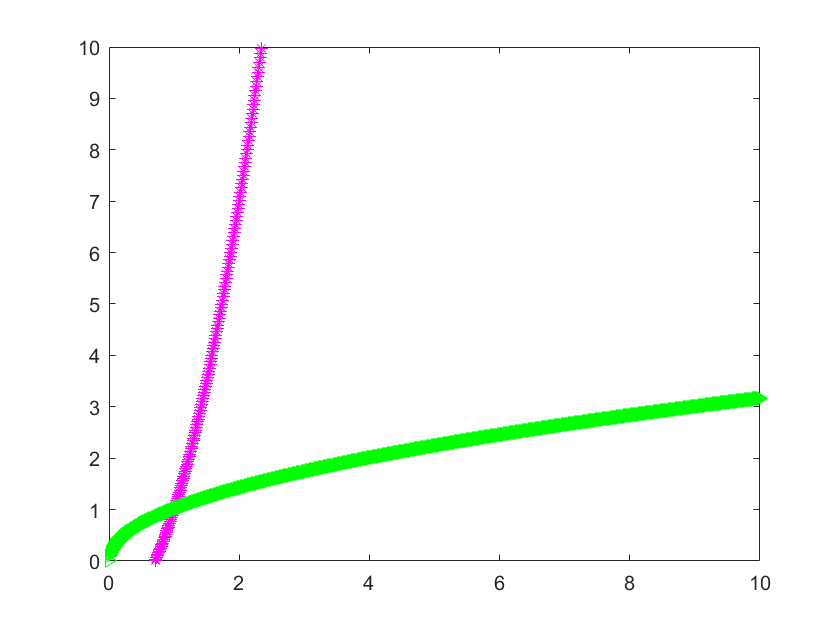


plot(x, y_a, 'm:*')
ylim([0 10])

hold on

plot(x, y_b, 'g>')

hold off

Another important feature to add to a graph is a title and axis labels. You can do this using the commands `title("your_title")`, `ylabel("your_y_label")`, and `xlabel("your_x_label"). `

If you are plotting multiple curves, you can create a legend using `legend("first", "second", ...).` Just make sure the order you use matches the order you've plotted your cruves. 

Finally, you can set axis limits using `xlim([lower_limit upper_limit]) `and `ylim([lower_limit upper_limit]).`

You can include these calls after using the `plot` command:

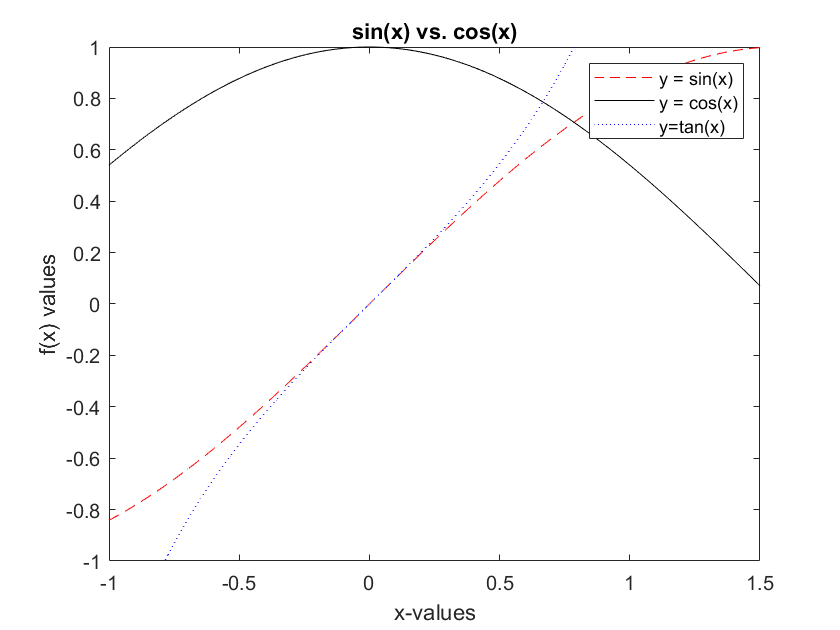

%% A complete graph

x = linspace(-2*pi, 2*pi, 1000);
y1 = sin(x);
y2 = cos(x);
y3 = tan(x);
plot(x,y1, 'r--')
hold on
plot(x,y2,'k')
plot(x, y3, 'b:')
hold off
title("sin(x) vs. cos(x)")

xlabel('x-values')
ylabel('f(x) values')

legend("y = sin(x)", "y = cos(x)", "y=tan(x)") % keep track of order!

% We can also set axis limits. 
xlim([-1 1.5]) 
ylim([-1 1])

You try: Revist your plot of $y = 2x^2-1$ with $y = \sqrt{x$. Add a title, legend, and $x$ and $y$ labels. 

%% Code here.

clc % clear variables to avoid confusion 

x = linspace(0,10,1000); % pick your domain wisely!

x =          0    0.0100    0.0200    0.0300    0.0400    0.0501    0.0601    0.0701    0.0801    0.0901    0.1001    0.1101    0.1201    0.1301    0.1401    0.1502    0.1602    0.1702    0.1802    0.1902    0.2002    0.2102    0.2202    0.2302    0.2402    0.2503    0.2603    0.2703    0.2803    0.2903    0.3003    0.3103    0.3203    0.3303    0.3403    0.3504    0.3604    0.3704    0.3804    0.3904    0.4004    0.4104    0.4204    0.4304    0.4404    0.4505    0.4605    0.4705    0.4805    0.4905


y_a = 2*x.^2 - 1;

y_a =    -1.0000   -0.9998   -0.9992   -0.9982   -0.9968   -0.9950   -0.9928   -0.9902   -0.9872   -0.9838   -0.9800   -0.9758   -0.9711   -0.9661   -0.9607   -0.9549   -0.9487   -0.9421   -0.9351   -0.9277   -0.9198   -0.9116   -0.9030   -0.8940   -0.8846   -0.8747   -0.8645   -0.8539   -0.8429   -0.8315   -0.8196   -0.8074   -0.7948   -0.7818   -0.7683   -0.7545   -0.7403   -0.7257   -0.7106   -0.6952   -0.6794   -0.6631   -0.6465   -0.6295   -0.6120   -0.5942   -0.5760   -0.5573   -0.5383   -0.5188


y_b = sqrt(x);

y_b =          0    0.1001    0.1415    0.1733    0.2001    0.2237    0.2451    0.2647    0.2830    0.3002    0.3164    0.3318    0.3466    0.3607    0.3744    0.3875    0.4002    0.4125    0.4245    0.4361    0.4474    0.4585    0.4693    0.4798    0.4901    0.5003    0.5102    0.5199    0.5294    0.5388    0.5480    0.5571    0.5660    0.5747    0.5834    0.5919    0.6003    0.6086    0.6167    0.6248    0.6328    0.6406    0.6484    0.6561    0.6637    0.6712    0.6786    0.6859    0.6932    0.7004


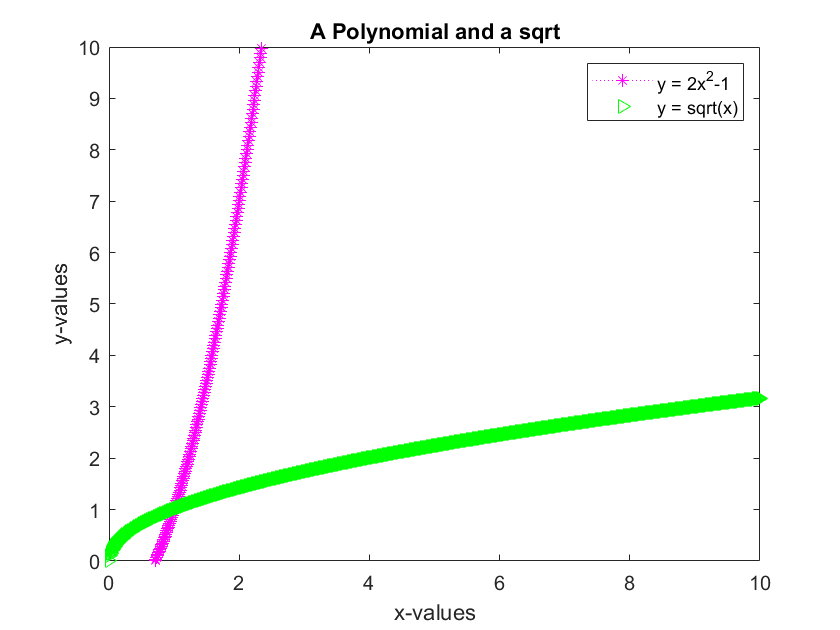


plot(x, y_a, 'm:*')

hold on

plot(x, y_b, 'g>')

hold off

xlim([0,10])
ylim([0 10])

title("A Polynomial and a sqrt")
legend("y = 2x^2-1", "y = sqrt(x)")
xlabel("x-values")
ylabel("y-values")

## Histograms and Scatter Plots

There are many other types of plots that can be created using MATLAB, but in this notebook we will just look at scatter plots and histograms. Recall that if you come across another type of plot, Google is your friend!

%% Creating a histogram of random values.

X = randi(10, 1, 10) % just creating some randome data

X =      8     7     1     9    10     8     1     4     8     8


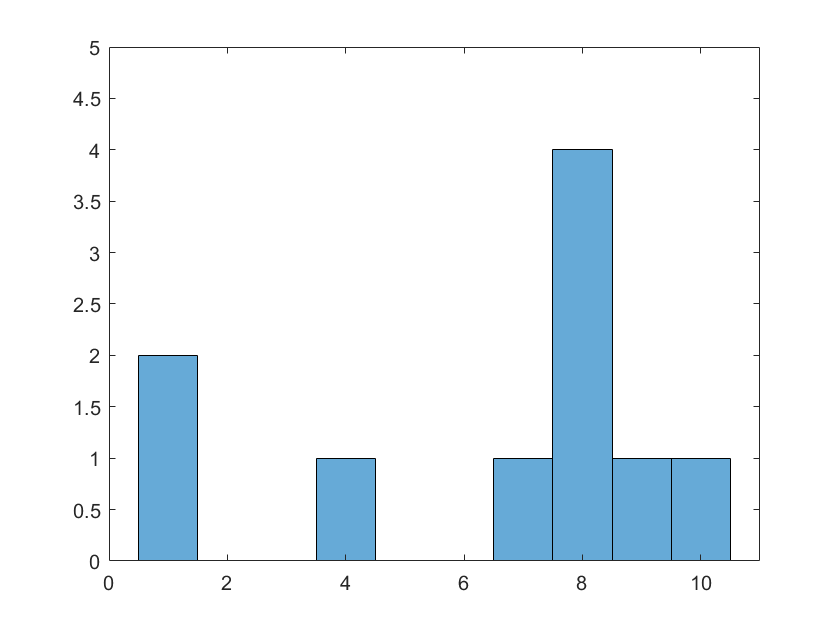

histogram(X)
xlim([0 11])
ylim([0 5])

We can also create a a scatterplot using a similar call.

%% Creating a scatterplot of random values
Y = 2*X+2*rand(1,10) - 1 % just creating some random data

Y =    16.2243   14.1079    2.3119   18.5013   20.7136   16.8352    2.4923    8.2815   16.7150   16.5038
   16.2691   14.1822    2.1790   18.4317   20.6183   16.3225    2.6947    8.2304   16.8562   16.4896
   16.6730   14.0991    2.3390   18.9976   20.3433   16.5523    2.9727    8.7111   16.2815   16.8770
   16.4775   14.4898    2.2101   18.8116   20.9360   16.9791    2.3278    8.6246   16.7311   16.3531
   16.6237   14.1932    2.5102   18.4857   20.1248   16.5493    2.8378    8.5906   16.1378   16.4494
   16.2364   14.8959    2.9064   18.8944   20.7306   16.3304    2.7391    8.6604   16.8367   16.9635
   16.1771   14.0991    2.6289   18.1375   20.6465   16.6195    2.9542    8.0476   16.1386   16.0423
   16.8296   14.0442    2.1015   18.3900   20.8332   16.3606    2.0319    8.3488   16.5882   16.9730
   16.7669   14.5573    2.3909   18.9274   20.3983   16.7565    2.3569    8.4513   16.3662   16.1892
   16.9345   14.7725    2.0546   18.9175   20.7498   16.4139    2.6627    8.2409   16.8

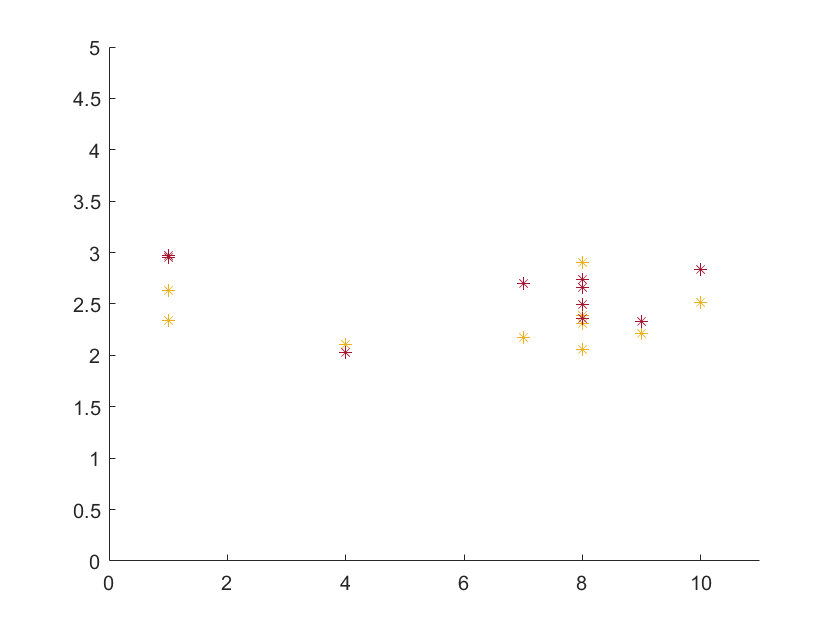

scatter(X,Y,'*')
xlim([0 11])
ylim([0 5])

Now let's graph the number of awards nominations Beyonce has received each year since 2003. 

This first code block just loads the data set you will need. 

%% Import Beyonce data set.

load beyonce.mat


In the code block below, create a histogram using the variable `total_noms. `Upgrade your plot by adding a title and playing with different colors. Remember you can always get hints by typing `doc histogram `to explore the available options. 

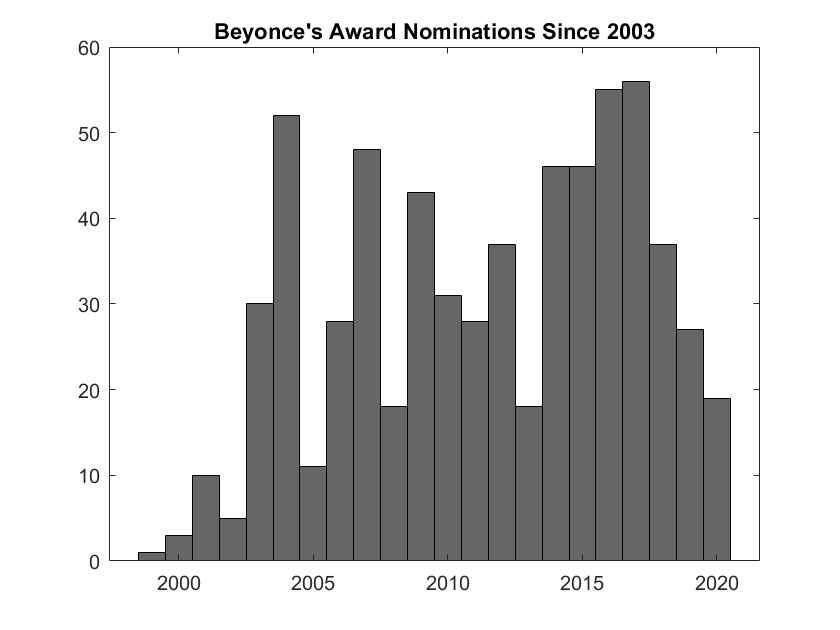

%% Code here.

% Sample Solution 

histogram(total_noms, 'FaceColor', 'black')
title("Beyonce's Award Nominations Since 2003")

In the code block below, create a scatter plot of number`_noms `against `nom_years. `Again, personalize your plot by adding a title, labels, and playing with different colors. Remember you can always get hints by typing `doc scatter `to explore the available options. 

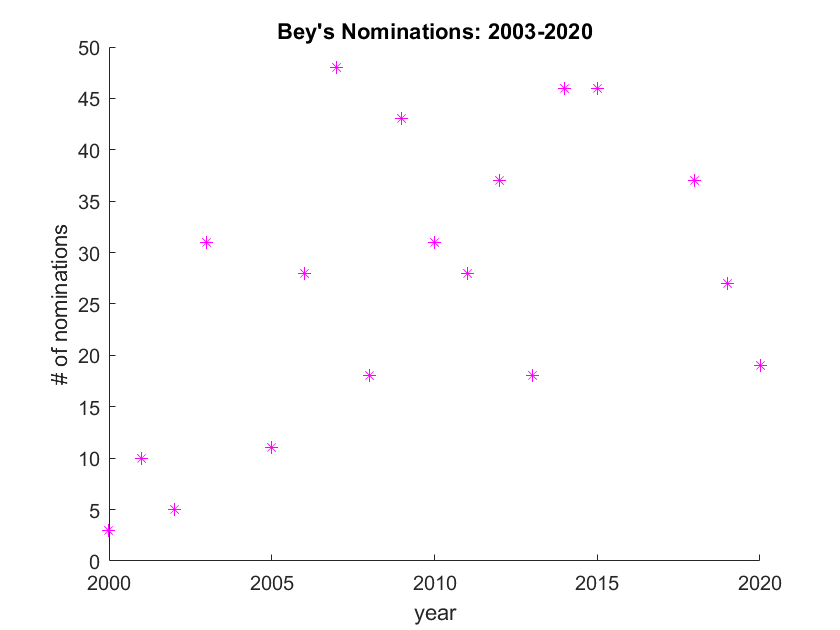

%% Code here.

% Sample Solution

scatter(nom_years, number_noms, 'm*')
title("Bey's Nominations: 2003-2020")
xlabel("year")
ylabel("# of nominations")

ylim([0 50])

That's it for this notebook! Note that there are tons of other plots and visualizations you can create using MATLAB, and this is just an introduction. You can even create 3D plots. Check MATLAB's documentation if you are interested in those!

## Disclaimers and References

*This notebook was written for the *[*The EDGE Program*](https://www.edgeforwomen.org/)* by Anila Yadavalli, Ph. D., 2021.*

*Redistribution of the material contained in this repository is conditional on acknowledgement of Anila Yadavalli, Ph.D.'s original authorship. *

*The Beyonce Data Set used in this notebook is a cleaned and modified version of the *[Storytelling with Data - The Beyonce Editition](https://dataverse.tdl.org/dataset.xhtml?persistentId=doi:10.18738/T8/XL8NIX) from The Texas Data Repository.